## Load functions

% this file should be in the same directory as the /functions dir
% restoredefaultpath;
addpath(['~/Documents/Courses/'...
    'ELEC-E5620 Audio Signal Processing/'...
    'Demo_FVN/matlab/functions']);

### Load soundfile

clear all;
addpath(['~/Documents/Courses/ELEC-E5620 Audio Signal Processing/'...
    'Demo_FVN/snd']);

[X, Fs] = audioread('pori.wav');

# Collect multiple uniform segments into matrix

starttime = 0.1;    % start time (seconds)
endtime = 2.2;      % don't get any window past this point
wintime = 2048/Fs;  % window duration (seconds) - paper uses 2048 samples
% wintime = 0.04;   % window duration (seconds) - paper uses 2048 samples
hoptime = wintime;

rangetime = endtime-starttime;
nWin = floor(rangetime/hoptime);
nWinSamps = floor(wintime * Fs);

segments = zeros(nWinSamps, nWin);

for i = 1:nWin
    st = starttime + (hoptime * (i-1));
    st = floor(st*Fs);
    segments(:, i) = getSamples(X, st, nWinSamps);
%     subplot(nWin,1,i);
%     plot(segments(:,i)); ylim([-1 1] *0.03); hold on;
end
hold off;

clear X starttime endtime wintime hoptime rangetime nWin nWinSamps st i

## LPC spectral estimate on matrix

#### Run above segmentation to populate 'seg' variable.

lpcOrder = 6;        % LPC All-pole coeff order
frq_resolution = 2048;   % freqz resolution of LPC filter (number of points to generate)

[mags, mags_norm, freqs, coeffs] = ...
    lpcData(segments, lpcOrder, frq_resolution, Fs);

### [Alt] LPC spectral estimate on cell array

lpcOrder = 6;            % LPC Allpole coeff order
frq_resolution = 2048;   % freqz resolution of LPC filter (number of points to generate)

nSig     = length(seg);  % number of signals to analyze
specEnv  = zeros(frq_resolution, nSig); % a matrix to hold all the segments' spectral envs
specNorm = zeros(frq_resolution, nSig);

for i = 1:nSig
    [mags mags_norm freqs coeffs] = ...
        lpcData(seg{i}, lpcOrder, frq_resolution, Fs);
    specEnv(:, i)  = mags;
    specNorm(:, i) = mags_norm;
end

mags = specEnv;
mags_norm = specNorm;

clear nSig specEnv specNorm

#### Manupulate magnitudes for plotting

% offset normalized magnitudes by segment's RMS
segrms = mag2db(rms(segments)); % get rms of each segment
segrms = segrms - max(segrms);  % shift rms's max to 0

% shift each segment response by it's rms
mags_rms_shift = mags_norm + segrms;  % normalized mags
% mags_rmsshift = mags + segrms;      % lpc mags

### Plot spectral estimate magnitudes

plot_rolloff_pnts = true; % plot rolloff point markers?
nchan = size(mags, 2);    % number of channels available
plot_idx = (1:nchan);   % which channels to plot
nplot = length(plot_idx); % number of channels being plotted

% select which data to plot
% data = mags_rms_shift(:, plot_idx);
data = mags_norm(:,plot_idx);
% data = mags(:,plot_idx);

plt = semilogx(freqs, data, "LineWidth", 1.5);

% generate colors for plot: hue_start, hue_span, num_plots
rgb = genColors(0.3, 0.1, nplot);

% plot cutoff markers
if ~plot_rolloff_pnts
    legend("Location", "SouthWest");
    legend('Position',[0.18 0.2 0.15 0.2]);
else
    hold on;
    rolloff  = -20;  % rolloff to detect, in dB
    min_freq = 750;  % don't search below this frequency
    
    [idxs, rollofffreqs, rolloffvals] = ...
        rolloffIdx(mags_norm(:,plot_idx), rolloff, min_freq, Fs);
    
    % keep track of the plots for legend management
    plts = {}; 
    plts{1} = plt; % add the spectral lines plot (from prev block)
    
    for i = 1:length(idxs)
        plt = semilogx( ...
            freqs(idxs(i)), data(idxs(i), i), ...
            "LineStyle", "none", "Marker", "*");
        plt.Annotation.LegendInformation.IconDisplayStyle = 'off';
        plts{i+1} = plt; % +1: plts{1} is the array of line plots 
    end
    
    % colors
    colororder([rgb; rgb]); % repeated so line and marker colors match
    
    legend([ ...
        plts{1}(1) ... % first of the line plots
        plts{2} ...    % first of the rolloff markers
        ],[ ...
            "segment spectrum" ...
            string(rolloff) + " rolloff point" ...
        ]);
    legend("Location", "West");
    % legend('Position',[0.18 0.2 0.15 0.2]);
    hold off;
end

colororder(rgb);
axis tight;    
xlim([80 20000]);
% ylim([-100 0])
xticks(125*2.^(0:7)) % octaves: 125 > 16000

clear nplot plot_idx

# Calculate first and last -20dB rolloff frequencies, and rms

nOutSegements = 24;
rolloff = -20; % rolloff to detect, in dB
min_freq = 750;

[idxs, rollofffreqs, rolloffvals] = ...
        rolloffIdx(mags_norm(:,[1 end]), rolloff, min_freq, Fs);
    
firstrms = rms(segments(:, 1));
lastrms = rms(segments(:, end));

% Evenly distribute frequency cutoff of each segment 
% bettween first and last segments' -20dB rolloff frequency
% rollofffreqs = linspace(f(1), f(end), nSig); % linear frequency spacing
 % logarithmic frequency spacing
rollofffreqs = exp(linspace( ...
    log(rollofffreqs(1)), log(rollofffreqs(end)), nOutSegements ...
    ));
rolloffrms = linspace(firstrms, lastrms, nOutSegements);

# Auto-segmentation

starttime = 0.1;    % start time (seconds)
winsize = 2048;  % analysis window size
hopsize = 500;   % analysis window hop

start = floor(starttime * Fs);
nwin = floor(((length(X) - start) - (winsize-hopsize)) / (hopsize+1));
segments = zeros(winsize, nwin);

% collect the "sliding window" of samples
winStSamps = zeros(nwin, 1);
for i = 1:nwin
    st = start + (hopsize * (i-1));
    winStSamps(i) = st;
    segments(:, i) = getSamples(X, st, winsize);
end

clear st start

## LPC spectral estimate on matrix

lpcOrder = 10;           % LPC All-pole coeff order
frq_resolution = 2048;   % freqz resolution of LPC filter (number of points to generate)

[mags, mags_norm, freqs, coeffs] = ...
    lpcData(segments, lpcOrder, frq_resolution, Fs);

[rollidxs, rollfreqs, rollvals] = rolloffIdx(mags_norm, -20, 1500, Fs)

rollidxs =         1251        1174        1052        1021        1019        1001        1007         962         956         960         939         923         889         886         902         885         877         863         801         804         768         771         744         749         717         710         714         710         692         669         669         652         656         670         646         654         637         634         621         622         607         597         592         580         579         586         586         584         564         554


rollfreqs = 	1.0e+04 *

    1.3160    1.2258    1.0828    1.0465    1.0441    1.0230    1.0301    0.9773    0.9703    0.9750    0.9504    0.9316    0.8918    0.8883    0.9070    0.8871    0.8777    0.8613    0.7887    0.7922    0.7500    0.7535    0.7219    0.7277    0.6902    0.6820    0.6867    0.6820    0.6609    0.6340    0.6340    0.6141    0.6188    0.6352    0.6070    0.6164    0.5965    0.5930    0.5777    0.5789    0.5613    0.5496    0.5437    0.5297    0.5285    0.5367    0.5367    0.5344    0.5109    0.4992


rollvals =   -19.9950  -18.7858  -16.2111  -15.5288  -15.4856  -15.1031  -15.2292  -14.3233  -14.2100  -14.2853  -13.8988  -13.6183  -13.0537  -13.0053  -13.2654  -12.9893  -12.8612  -12.6383  -11.6221  -11.6739  -11.0235  -11.0803  -10.5504  -10.6518   -9.9765   -9.8207   -9.9101   -9.8207   -9.4072   -8.8556   -8.8556   -8.4348   -8.5346   -8.8801   -8.2844   -8.4848   -8.0575   -7.9816   -7.6522   -7.6776   -7.2984   -7.0477   -6.9234   -6.6286   -6.6044   -6.7753   -6.7753   -6.7262   -6.2461   -6.0144


### Plot frequency rolloff by window

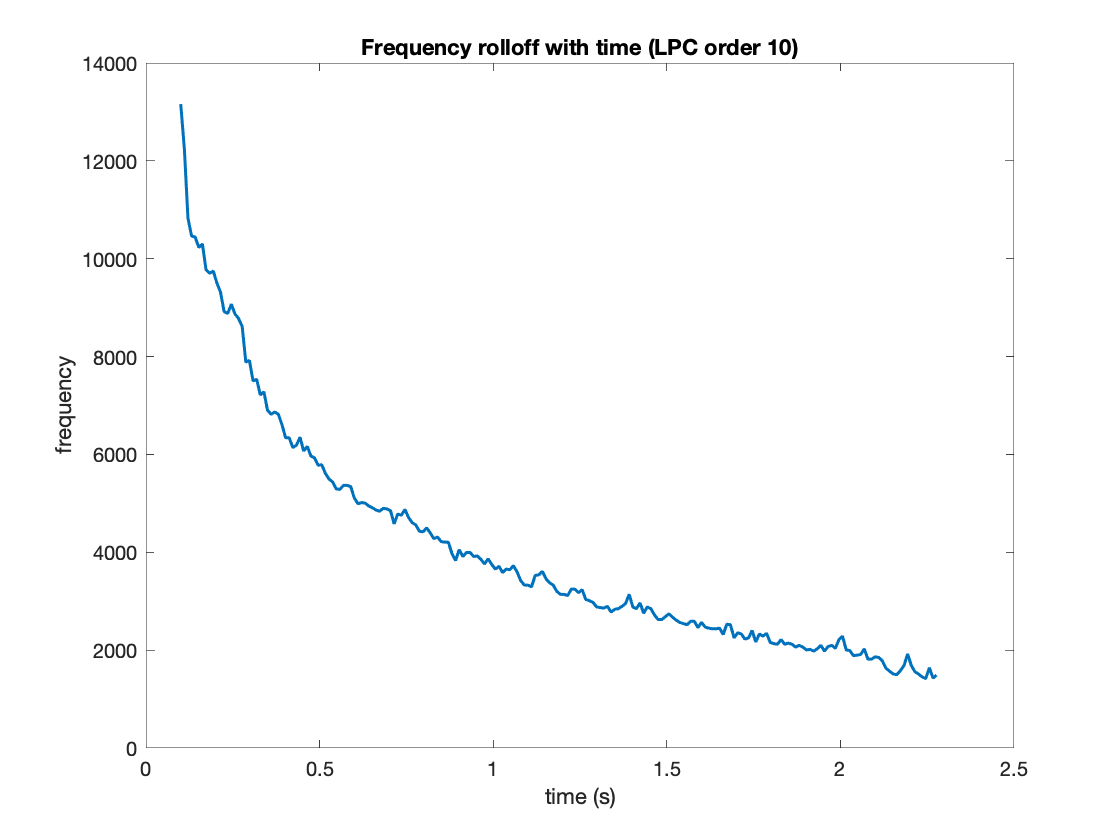

plot(winStSamps / Fs, rollfreqs, "LineWidth", 1.5);
xlabel('time (s)')
ylabel('frequency')
title(strcat("Frequency rolloff with time (LPC order ", string(lpcOrder), ")"))

### Find which analysis windows mark segment boundaries

frqHigh = rollfreqs(1);
frqLow  = 260; % found through inspection
segthresh = 0.05; % percentage of frqHigh to advance between segments
freqstep = frqHigh * segthresh;

segStartIdxs = [winStSamps(1)];
cnt = 1; % analysis window counter
nextBoundaryFrq = frqHigh - freqstep

nextBoundaryFrq = 1.2502e+04


while (nextBoundaryFrq >= frqLow) && (cnt <= length(rollidxs))
    thisfrq = rollfreqs(cnt)
    if (thisfrq < nextBoundaryFrq)
        % add this window's start frame to the segment boundary list
        segStartIdxs = [segStartIdxs winStSamps(cnt)];
        
        nextBoundaryFrq = nextBoundaryFrq - freqstep
    end
    cnt = cnt+1;
end

thisfrq = 1.3160e+04

thisfrq = 1.2258e+04

nextBoundaryFrq = 1.1844e+04

thisfrq = 1.0828e+04

nextBoundaryFrq = 1.1186e+04

thisfrq = 1.0465e+04

nextBoundaryFrq = 1.0528e+04

thisfrq = 1.0441e+04

nextBoundaryFrq = 9.8701e+03

thisfrq = 1.0230e+04

thisfrq = 1.0301e+04

thisfrq = 9.7734e+03

nextBoundaryFrq = 9.2121e+03

thisfrq = 9.7031e+03

thisfrq = 9750

thisfrq = 9.5039e+03

thisfrq = 9.3164e+03

thisfrq = 8.9180e+03

nextBoundaryFrq = 8.5541e+03

thisfrq = 8.8828e+03

thisfrq = 9.0703e+03

thisfrq = 8.8711e+03

thisfrq = 8.7773e+03

thisfrq = 8.6133e+03

thisfrq = 7.8867e+03

nextBoundaryFrq = 7.8961e+03

thisfrq = 7.9219e+03

thisfrq = 7500

nextBoundaryFrq = 7.2381e+03

thisfrq = 7.5352e+03

thisfrq = 7.2188e+03

nextBoundaryFrq = 6.5801e+03

thisfrq = 7.2773e+03

thisfrq = 6.9023e+03

thisfrq = 6.8203e+03

thisfrq = 6.8672e+03

thisfrq = 6.8203e+03

thisfrq = 6.6094e+03

thisfrq = 6.3398e+03

nextBoundaryFrq = 5.9221e+03

thisfrq = 6.3398e+03

thisfrq = 6.1406e+03

thisfrq = 6.1875e+03

thisfrq = 6.3516e+03

thisfrq = 6.0703e+03

thisfrq = 6.1641e+03

thisfrq = 5.9648e+03

thisfrq = 5.9297e+03

thisfrq = 5.7773e+03

nextBoundaryFrq = 5.2641e+03

thisfrq = 5.7891e+03

thisfrq = 5.6133e+03

thisfrq = 5.4961e+03

thisfrq = 5.4375e+03

thisfrq = 5.2969e+03

thisfrq = 5.2852e+03

thisfrq = 5.3672e+03

thisfrq = 5.3672e+03

thisfrq = 5.3438e+03

thisfrq = 5.1094e+03

nextBoundaryFrq = 4.6061e+03

thisfrq = 4.9922e+03

thisfrq = 5.0156e+03

thisfrq = 5.0039e+03

thisfrq = 4.9453e+03

thisfrq = 4.9102e+03

thisfrq = 4.8633e+03

thisfrq = 4.8398e+03

thisfrq = 4.8984e+03

thisfrq = 4.8867e+03

thisfrq = 4.8516e+03

thisfrq = 4.5820e+03

nextBoundaryFrq = 3.9480e+03

thisfrq = 4.7813e+03

thisfrq = 4.7578e+03

thisfrq = 4875

thisfrq = 4.7109e+03

thisfrq = 4.6055e+03

thisfrq = 4.5586e+03

thisfrq = 4.4297e+03

thisfrq = 4.4180e+03

thisfrq = 4500

thisfrq = 4.3945e+03

thisfrq = 4.2773e+03

thisfrq = 4.3125e+03

thisfrq = 4.2188e+03

thisfrq = 4.2070e+03

thisfrq = 4.2070e+03

thisfrq = 3.9727e+03

thisfrq = 3.8320e+03

nextBoundaryFrq = 3.2900e+03

thisfrq = 4.0547e+03

thisfrq = 3.9141e+03

thisfrq = 3.9961e+03

thisfrq = 3.9961e+03

thisfrq = 3.9141e+03

thisfrq = 3.9258e+03

thisfrq = 3.8555e+03

thisfrq = 3.7617e+03

thisfrq = 3.8672e+03

thisfrq = 3750

thisfrq = 3.6563e+03

thisfrq = 3.7148e+03

thisfrq = 3.5859e+03

thisfrq = 3.6563e+03

thisfrq = 3.6445e+03

thisfrq = 3.7266e+03

thisfrq = 3.5977e+03

thisfrq = 3.4219e+03

thisfrq = 3.3281e+03

thisfrq = 3.3281e+03

thisfrq = 3.2930e+03

thisfrq = 3.5273e+03

thisfrq = 3.5391e+03

thisfrq = 3.6094e+03

thisfrq = 3.4570e+03

thisfrq = 3375

thisfrq = 3.3281e+03

thisfrq = 3.1992e+03

nextBoundaryFrq = 2.6320e+03

thisfrq = 3.1406e+03

thisfrq = 3.1406e+03

thisfrq = 3.1172e+03

thisfrq = 3.2461e+03

thisfrq = 3.2461e+03

thisfrq = 3.1758e+03

thisfrq = 3.2344e+03

thisfrq = 3.0352e+03

thisfrq = 3.0117e+03

thisfrq = 2.9766e+03

thisfrq = 2.8828e+03

thisfrq = 2.8711e+03

thisfrq = 2.8594e+03

thisfrq = 2.8945e+03

thisfrq = 2.7773e+03

thisfrq = 2.8359e+03

thisfrq = 2.8477e+03

thisfrq = 2.8945e+03

thisfrq = 2.9531e+03

thisfrq = 3.1406e+03

thisfrq = 2.8828e+03

thisfrq = 2.8477e+03

thisfrq = 2.9648e+03

thisfrq = 2.7539e+03

thisfrq = 2.8828e+03

thisfrq = 2.8477e+03

thisfrq = 2.7188e+03

thisfrq = 2625

nextBoundaryFrq = 1.9740e+03

thisfrq = 2625

thisfrq = 2.6836e+03

thisfrq = 2.7422e+03

thisfrq = 2.6719e+03

thisfrq = 2.6133e+03

thisfrq = 2.5664e+03

thisfrq = 2.5430e+03

thisfrq = 2.5195e+03

thisfrq = 2.5898e+03

thisfrq = 2.5898e+03

thisfrq = 2.4609e+03

thisfrq = 2.5664e+03

thisfrq = 2.4727e+03

thisfrq = 2.4492e+03

thisfrq = 2.4375e+03

thisfrq = 2.4375e+03

thisfrq = 2.4492e+03

thisfrq = 2.3203e+03

thisfrq = 2.5313e+03

thisfrq = 2.5195e+03

thisfrq = 2250

thisfrq = 2.3555e+03

thisfrq = 2.3320e+03

thisfrq = 2.2266e+03

thisfrq = 2250

thisfrq = 2.4023e+03

thisfrq = 2.1680e+03

thisfrq = 2.3320e+03

thisfrq = 2.2852e+03

thisfrq = 2.3438e+03

thisfrq = 2.1563e+03

thisfrq = 2.1328e+03

thisfrq = 2.1211e+03

thisfrq = 2.2148e+03

thisfrq = 2.1211e+03

thisfrq = 2.1445e+03

thisfrq = 2.1211e+03

thisfrq = 2.0625e+03

thisfrq = 2.0977e+03

thisfrq = 2.0625e+03

thisfrq = 2.0039e+03

thisfrq = 2.0156e+03

thisfrq = 1.9805e+03

thisfrq = 2.0273e+03

thisfrq = 2.0977e+03

thisfrq = 1.9805e+03

thisfrq = 2.0742e+03

thisfrq = 2.0977e+03

thisfrq = 2.0391e+03

thisfrq = 2.2148e+03

thisfrq = 2.2852e+03

thisfrq = 2.0039e+03

thisfrq = 1.9922e+03

thisfrq = 1.8867e+03

nextBoundaryFrq = 1.3160e+03

thisfrq = 1.8984e+03

thisfrq = 1.9102e+03

thisfrq = 2.0273e+03

thisfrq = 1.8164e+03

thisfrq = 1.8164e+03

thisfrq = 1.8633e+03

thisfrq = 1.8516e+03

thisfrq = 1.7813e+03

thisfrq = 1.6289e+03

thisfrq = 1.5703e+03

thisfrq = 1.5117e+03

thisfrq = 1500

thisfrq = 1.5820e+03

thisfrq = 1.6875e+03

thisfrq = 1.9219e+03

thisfrq = 1.6875e+03

thisfrq = 1.5586e+03

thisfrq = 1.5117e+03

thisfrq = 1.4531e+03

thisfrq = 1.4180e+03

thisfrq = 1.6406e+03

thisfrq = 1.4297e+03

thisfrq = 1.4883e+03


if cnt == length(rollidxs)
    warning("reached the end of the analysis window list")
end
if nextBoundaryFrq < frqLow
    disp("*** next boundary fell below frqLow ***")
end

#### plot segment divisions

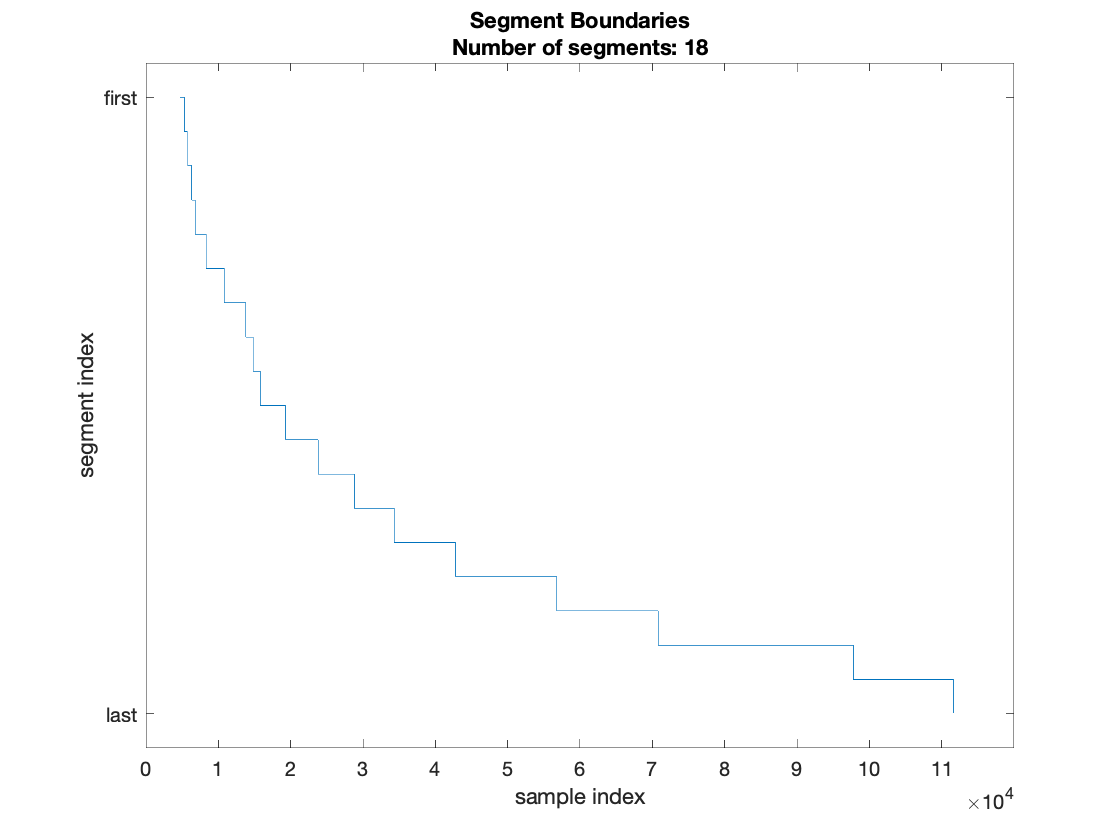

segBoundaries = [segStartIdxs length(X)]; % add the endpoint in for plotting
nBoundaries = length(segBoundaries);
stairs(segBoundaries, nBoundaries:-1:1);
yticks([1 nBoundaries])
xticks(round(segStartIdxs(1), -4):10000:round(length(X),-4))
yticklabels(["last" "first"]);
ylabel('segment index')
xlabel('sample index')
ylim([0,nBoundaries+1])
title({"Segment Boundaries", ...
    sprintf("Number of segments: %d", length(segStartIdxs))})


clear nBoundaries segBoundaries

### Calculate rolloff of velvet noise

velvetLPCorder = 60;
velvetRolloff = -10;
velvetFrqs = 10:70:500;
nVelvets = length(velvetFrqs);
velvetDur = floor(1.5 * Fs);
velvetMtx = zeros(velvetDur, nVelvets);
analysisResolution = 4096;

for i = 1:nVelvets
    velvetMtx(:, i) = velvet(velvetDur, velvetFrqs(i), Fs);
end

lpcOrder = 10;           % LPC All-pole coeff order
frq_resolution = 2048;   % freqz resolution of LPC filter (number of points to generate)

[mags, mags_norm, freqs, coeffs] = ...
    lpcData(velvetMtx, velvetLPCorder, analysisResolution, Fs);

[rollidxs, rollfreqs, rollvals] = rolloffIdx(mags_norm, velvetRolloff, 50, Fs)

plotOneFFT(velvetMtx(:,end), size(velvetMtx, 1), Fs)

% clear X starttime endtime wintime hoptime rangetime nWin nWinSamps st i

starttime = 0.1;         % start time (seconds)
wintime = 2048/Fs;       % window duration (seconds)
frq_resolution = 4096;   % freqz resolution of LPC filter (number of points to generate)
% slide analysis window until the -20 cutoff frequency crosses the 
% specified frequency
hop = 1;       % window hop size to slide on each iteration (fraction of wintime)
maxSlide = 0.5;   % bail if the window slides this far without getting result

winSamps = floor(wintime * Fs);
hopSamp = floor(hop * winSamps);
winStart = floor(starttime * Fs);
maxSlideSamp = floor(maxSlide * Fs);

segStartSamps = [winStart]; % store the location of the first segment

maxCnt = ceil(maxSlideSamp/hopSamp);

cutoffFreq = 20000;
thisrms = 20;
for i = 2:length(rollofffreqs)
    rollFrq = rollofffreqs(i);
    rollRms = rolloffrms(i);
    cnt = 0;
%      && (cnt < maxCnt)
    while (cutoffFreq > rollFrq) || (thisrms > rollRms)
    
        % advance the window
        winStart = winStart + hopSamp;
        
        % retrieve samples
        segment = getSamples(X, winStart, winSamps);
        
        % calculate LPC spectrum estimate, convert to magnitudes dB
        [lpc_coefs, residual] = lpc(segment, lpcOrder);
        [H, w] = freqz(1, lpc_coefs, frq_resolution);
        spectrum = mag2db(abs(H));
        % normalize to channel peak
        specNorm = db2mag(spectrum);
        specNorm = specNorm ./ max(specNorm); 
        specNorm = mag2db(specNorm);
        
        clear spectrum;
        
        % calculate the -20dB cutoff freq
        srchSpec = specNorm(minFrqIdx:end);
        [d, ix] = min(abs(srchSpec - rolloff));
        ix = ix + minFrqIdx-1; % restore index
        cutoffFreq = w(ix)/pi * (Fs/2);
        
        thisrms = rms(segment); % calc rms
 
        cnt = cnt+1;
    end
    if cnt <= maxCnt
        segStartSamps = [segStartSamps winStart];
        fprintf("got out in %d iters at %dHz %f rms (%d/%f)", cnt, round(cutoffFreq), thisrms, round(rollFrq), rollRms);
    else
        warning("Exceeded rolloff search range on window " + i)
    end
end

steps = segStartSamps(2:end) - segStartSamps(1:end-1);

plot(steps)

## Assign segment boundary to each frequency division

starttime = 0.1;         % start time (seconds)
wintime = 2048/Fs;       % window duration (seconds)
frq_resolution = 4096;   % freqz resolution of LPC filter (number of points to generate)
% slide analysis window until the -20 cutoff frequency crosses the 
% specified frequency
hop = 1;       % window hop size to slide on each iteration (fraction of wintime)
maxSlide = 0.5;   % bail if the window slides this far without getting result

winSamps = floor(wintime * Fs);
hopSamp = floor(hop * winSamps);
winStart = floor(starttime * Fs);
maxSlideSamp = floor(maxSlide * Fs);

segStartSamps = [winStart]; % store the location of the first segment

maxCnt = ceil(maxSlideSamp/hopSamp);

cutoffFreq = 20000;
thisrms = 20;
for i = 2:length(rollofffreqs)
    rollFrq = rollofffreqs(i);
    rollRms = rolloffrms(i);
    cnt = 0;
%      && (cnt < maxCnt)
    while (cutoffFreq > rollFrq) || (thisrms > rollRms)
    
        % advance the window
        winStart = winStart + hopSamp;
        
        % retrieve samples
        segment = getSamples(X, winStart, winSamps);
        
        % calculate LPC spectrum estimate, convert to magnitudes dB
        [lpc_coefs, residual] = lpc(segment, lpcOrder);
        [H, w] = freqz(1, lpc_coefs, frq_resolution);
        spectrum = mag2db(abs(H));
        % normalize to channel peak
        specNorm = db2mag(spectrum);
        specNorm = specNorm ./ max(specNorm); 
        specNorm = mag2db(specNorm);
        
        clear spectrum;
        
        % calculate the -20dB cutoff freq
        srchSpec = specNorm(minFrqIdx:end);
        [d, ix] = min(abs(srchSpec - rolloff));
        ix = ix + minFrqIdx-1; % restore index
        cutoffFreq = w(ix)/pi * (Fs/2);
        
        thisrms = rms(segment); % calc rms
 
        cnt = cnt+1;
    end
    if cnt <= maxCnt
        segStartSamps = [segStartSamps winStart];
        fprintf("got out in %d iters at %dHz %f rms (%d/%f)", cnt, round(cutoffFreq), thisrms, round(rollFrq), rollRms);
    else
        warning("Exceeded rolloff search range on window " + i)
    end
end

steps = segStartSamps(2:end) - segStartSamps(1:end-1);

plot(steps)

### Plot RMS of each whitened segment

whiteRMS = rms(white_segments)
plot(mag2db(whiteRMS))

# Plot segmented FFT

Uses single or multi-segment fft function below

% plotOneFFT(seg{1}, Fs)
plotMultiFFT(segments, 512, Fs)

legend()

# :: functions :: PlotOneFFT, PlotMultiFFT 

- Note: **fftshift()** shifts bins to put 0Hz at the center (odd N) or center +1 (even N)

% function [mags mags_norm freqs coeffs] = lpcData(signal, lpc_order, freq_resolution, Fs, whiten)
%     % [mags freqs coeffs] = lpcData(signal, lpc_order, freq_resolution, whiten)
%     % (((input)))
%     %           signal : column-major input signal matrix
%     %        lpc_order : order of LPC filter to generate
%     %  freq_resolution : number of frequencies to evaluate the magnitude 
%     %                    spectrum
%     %               Fs : sample rate
%     %           whiten : optional flag to perform freq analysis on the LPC
%     %                    coefficients treated as a whitening filter
%     % (((output)))
%     %      mags : frequency magnitudes of the spectral estimate in dB
%     % mags_norm : normalized frequency magnitudes of the spectral estimate in dB
%     %     freqs : frequencies corresponding to the spectral magnitudes
%     %    coeffs : the LPC coefficients
%     
%     % enforce column vector on 1-channel signal
%     if size(signal, 1) == 1
%         signal =  signal';
%     end
%     % handle whitening option
%     whitenfilt = false; % default: analyse a whitening filter
%     if nargin > 4
%         if whiten > 0
%             whitenfilt = true
%         end
%     end
%     
%     coeffs = lpc(signal, lpc_order)'; % note: column-major
%     nchan = size(signal, 2);
%     mags = zeros(freq_resolution, nchan);
%     mags_norm = zeros(freq_resolution, nchan);
%     freqs = zeros(freq_resolution, 1);
%     % 
%     for i = 1:nchan
%         if whitenfilt
%             [H, w] = freqz(coeffs(:, i), 1, freq_resolution);
%         else
%             [H, w] = freqz(1, coeffs(:,i), freq_resolution);
%         end
%         m = abs(H);
%         mags_norm(:, i) = mag2db(m./max(m));
%         mags(:, i) = mag2db(m);
%     end
%     freqs(:,1) = (w/pi) * (Fs/2);
% end

function plotOneFFT(signal, N, Fs)
    zoom = [0 Fs/2];         % "zoom in" on this freq range
    H = fft(signal, N);
    mag = abs(H)*2/N;
    mag = fftshift(mag);
    
    % the plot indices of freqbins (of fftshift'd spectrum)
    pidx = (floor(N/2)+1:N); % spectrum 0 -> Nyquist
    mag = mag(pidx);
    mag = mag2db(mag);
    f = linspace(0, Fs/2, length(mag));
    
%     stem(f, mag);
    semilogx(f, mag);
    xlim(zoom);              % zoom via plot limits
    ylim([-150 -50])
end

function plotMultiFFT(signalCell, N, Fs)
    % plotMultiFFT(signalCell, N, Fs)
    %    [input]
    % signalCell: a cell array containing signals to perform FFT
    %          N: FFT size
    %         Fs: sample rate of signal
    
    mags = zeros(N, length(signalCell)); % matrix to hold FFT analysis
    
    % "zoom in" on this freq range (via xlim)
    % Change this is you want a specific freq range
    zoom = [0 Fs/2];                     
    
    nSig = length(signalCell);
    for i=1:nSig
        mags(:,i) = fft(signalCell{i}, N);
    end
    mags = abs(mags)*2/N;
    mags = fftshift(mags);    
    
    % the plot indices of freqbins (of fftshift'd spectrum)
    pidx = (floor(N/2)+1:N);        % spectrum 0 -> Nyquist
    mags = mags(pidx, :);
    mags = mags./max(max(mags));    % normalize spectra
    mags = mag2db(mags);
%     mags = mags./max(mags);
    
    f = linspace(0, Fs/2, length(mags)); % bin frequencies 
    semilogx(f, mags);
    xlim(zoom);
    ylim([-80 0]);
end

% function Y = getSamples(X, st, N)
%     % getSamples(X, st, N)
%     %    [input]
%     %  X: signal buffer
%     % st: start sample of returned frames
%     %  N: number of samples to return
%     if st+(N-1) > length(X)
%         warning('requested samples exceed the length of ht input buffer, clamping at the end');
%         N = length(X) - st;
%     end
%     Y = X(st:st+N-1);
% end

function Y = getSamplesDur(X, st, D, Fs)
    % getSamplesDur(X, st, N)
    %  INPUT
    %      X : signal buffer
    %     st : start time of returned frames
    %      D : duration of window to return
    %     Fs : sample rate of signal buffer
    stSamp = floor(Fs * st);
    durSamp = floor(Fs * D);
    Y = getSamples(X, stSamp, durSamp);
end

% function rgb = genColors(hue_start, hue_span, num_cols)
%     % genColors(hue_start, hue_span, num_plots)
%     %      INPUT
%     %  hue_start : hue start position {0,1}
%     %   hue_span : hue range {0,1}
%     %   num_cols : number of colors to generate
%     hue = linspace(hue_start, hue_start+hue_span, num_cols); % hue
%     sat = linspace(1, 1, num_cols);     % saturation
%     val = linspace(0.2, 1, num_cols);   % value
%     hsv = [hue' sat' val']; 
%     rgb = hsv2rgb(hsv);
% end

function [idxs, freqs, vals] = rolloffIdx(mags, rolloff, min_freq, Fs)
    % idxs = rolloffIdx(mags, rolloff, min_freq, Fs)
    %          INPUTS
    %            mags : column-major matrix of NORMALIZED spectral magnitudes
    %         rolloff : dB level to search for in rolloff countour
    %        min_freq : search above this frequency (shrink the search space)
    % freq_resolution : number of points comprising the full magnitude
    %                   spectrum
    %              Fs : sample rate
    %    OUTPUTS
    %       idxs : vector of indicies closest to the rolloff
    %      freqs : frequencies at idxs
    %       vals : values in mags matrix at indxs
    
    % narrow the search space: omit part of the spectrum below min_freq
    nFreqs = length(mags);
    minFrqIdx = floor(min_freq/(Fs/2) * nFreqs);
    srchSpec = mags(minFrqIdx:end, :);
    
    % find closest values, by index
    [d, ix] = min(abs(srchSpec - rolloff));
    % restore index from min_freq offset
    idxs = ix + minFrqIdx-1;    
    
%     cols = 1:size(mags, 2);
%     freqs = sub2ind(size(mags), idxs, cols);
%     freqs = w(ix)/pi * (Fs/2);
    freqs = Fs/2 / nFreqs * (ix-1);
    
    vals = mags(idxs); % cutoff values in each segment
end

% calculate the -20dB cutoff freq
%         srchSpec = specNorm(minFrqIdx:end);
%         [d, ix] = min(abs(srchSpec - rolloff));
%         ix = ix + minFrqIdx-1; % restore index
%         cutoffFreq = w(ix)/pi * (Fs/2);